# HSFP Probabilities Test File

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 17/05/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Test Data: **ASSET Log Dif Returns & Smoothed Singal Data

"DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat"

""DATA-PROCESSED-SIG-SMTH_NORM-M-TTABLE-20070531-20230228.mat"

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for HSFP Fns folder

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/HSFP/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/HSFP/', exportName);

## 2. Load Test Data

#### 2.1 ASSET Log Dif Returns

fileName = "DATA-PROCESSED-INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat";
load(fileName)

#### 2.2 Scored Signal Data

fileName = "DATA-PROCESSED-SIG-SMTH_NORM-M-TTABLE-20070531-20230228.mat";
load(fileName)

% Get the number of rows in the timetable object
numRows = height(SIG_SMOOTHED_TT);

% Remove the first two rows
SIG_SMOOTHED_TT = SIG_SMOOTHED_TT(3:numRows, :);

## 3. Generate HSFP Time Conditioned Prs

Window_len = 60;
% Rolling window Prs
p_rw = rw_probs(ASSETCL_log_diff,Window_len);
% Exp Decay Prs
tau = 24;
p_es = es_probs(ASSETCL_log_diff, tau);

#### 3.1.1 Plot Time Conditioned (***** Fix export of plots to have 2 above each other **** currently done manually*) - might relate to pr_plot Fn

For some reason we need to run box twice to get right fig strucure (to fix later)

subplot(2,1,1);
HSFP_RW_plot = bar(ASSETCL_log_diff.Time, p_rw);
ylabel("Probability");
xlabel("Time");
title(['Rolling Window Conditioned Probabilities ( Window Length = ' num2str(Window_len) ')']);

subplot(2,1,2)
HSFP_ES_plot = bar(ASSETCL_log_diff.Time, p_es);
ylabel("Probability");
xlabel("Time");
title(['Exponential Decayed Conditioned Probabilities ( \tau = ' num2str(tau) ')']);
HSFP_TIME_CON_plot = gcf;

**Export Rolling Window Pr plot**

exportName = 'HSFP_TIME_CON_plot.pdf';
exportgraphics(HSFP_TIME_CON_plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 4. GENERAL INPUT SETUP: HSFP State-Conditioned Prs 

Use CPI as test 

alpha = 0.3;
gamma = 2;
h = 0.5;
Signal_series = SIG_SMOOTHED_TT.lagged_SACPIYOY_Index;
z_sig_target = -1.04;

### 4.1 Using Single Var: Crisp Prs

[p_cr,upper, lower] = cr_probs(Signal_series, alpha, z_sig_target);

### 4.2  Using Single Var: Kernel Prs

knl_check_prs = kl_probs(Signal_series,h , gamma , z_sig_target);
sum(knl_check_prs);

## 5. HSFP Time- & State-Conditioned Prs

### 5. 1 Entropy Pooling

Select a suitable prior. Here we use the exponential decay prior as this conditions by time before we condition by state using crisp condition.

post_pr = ep_probs(Signal_series, alpha, z_sig_target, ep_prior);

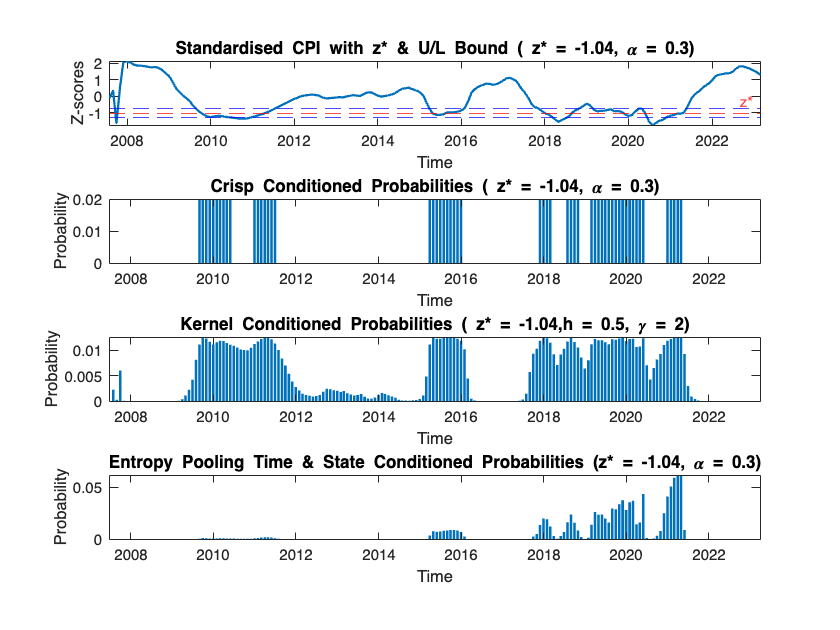

%%%%%%%  SIGNAL PLOT %%%%%%%%
subplot(4,1,1);
plot(SIG_SMOOTHED_TT.Time, Signal_series, 'LineWidth', 1.5);
hold on;
yline(z_sig_target, 'r--','Label', 'z*');
yline(upper, 'b--');
yline(lower, 'b--');
hold off;
ylabel("Z-scores");
xlabel("Time");
title(['Standardised CPI with z* & U/L Bound ( z* = ' num2str(z_sig_target) ', \alpha = ' num2str(alpha) ')']);


% close all (COMMENT OUT TO PLOT)
%%%%%%%  CRISP PLOT %%%%%%%%
subplot(4,1,2);
HSFP_CRISP_plot = bar(SIG_SMOOTHED_TT.Time, round(p_cr,2));
ylabel("Probability");
xlabel("Time");
title(['Crisp Conditioned Probabilities ( z* = ' num2str(z_sig_target) ', \alpha = ' num2str(alpha) ')']);

% % Adjust the spacing between the subplots
% spacing = 0.05;
% subplot(3,1,1);
% pos = get(gca, 'Position');
% pos(4) = pos(4) - spacing;
% set(gca, 'Position', pos);
% subplot(3,1,2);
% pos = get(gca, 'Position');
% pos(2) = pos(2) + spacing;
% pos(4) = pos(4) - spacing;
% set(gca, 'Position', pos);

%%%%%%%  KERNEL PLOT %%%%%%%%
subplot(4,1,3);
HSFP_KERNEL_plot = bar(SIG_SMOOTHED_TT.Time, knl_check_prs);
ylabel("Probability");
xlabel("Time");
title(['Kernel Conditioned Probabilities ( z* = ' num2str(z_sig_target) ',h = ' num2str(h) ', \gamma = ' num2str(gamma) ')']);
% Save the combined plot as an image file

%%%%%%%  ENTROPY POOL PLOT %%%%%%%%
subplot(4,1,4);
HSFP_EPOOL_plot = bar(SIG_SMOOTHED_TT.Time, post_pr);
ylabel("Probability");
xlabel("Time");
title(['Entropy Pooling Time & State Conditioned Probabilities (z* = ' num2str(z_sig_target) ', \alpha = ' num2str(alpha) ')']);

% Save the combined plot as an image file
HSFP_STATE_CON_plot = gcf;

#### **Export STATE CONDITIONED Plot**

post_pr =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0011    0.0011    0.0008    0.0006    0.0008    0.0010    0.0010    0.0008    0.0007    0.0006    0.0005    0.0004    0.0004    0.0004    0.0006    0.0009    0.0012    0.0016    0.0019    0.0019    0.0017    0.0011    0.0005    0.0002


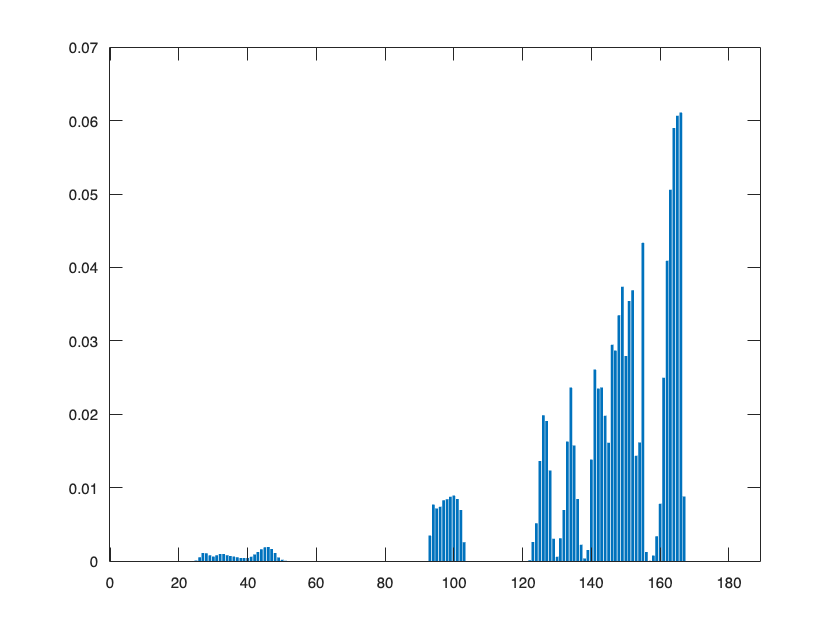

exportName = 'HSFP_STATE_CON_plot.pdf';
exportgraphics(HSFP_STATE_CON_plot, ...
    fullfile(imageExportpath,exportName),'Resolution',300);

Want to make it an independent function so you don't need to run the crisp Pr as input

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%